**EE 150**

**Signals and Systems**

** Lab 5 Sampling and Reconstruction**

Date Performed: 20241209

Name & ID:全苑裳2023533012 赵思哲2023533120

1. Load **Lab5_signal2.mat** with function **Load **to get the original signal. 

1.1 Analyze the original periodic signal. Plot the original signal and its spectrum. From the amplitude-frequency diagram, find out the bandwidth of the signal, name it as **fb** and print it.

1.2 Sample the original signal at 1.5 times of **fb** and then reconstruct it. Plot the sampled signal, the spectrum  of the sampled signal and the reconstructed signal.

1.3  Sample the original signal at 4 times of **fb** and then reconstruct it. Plot the sampled signal, the spectrum  of the sampled signal and the reconstructed signal.

Organize all the plots in a  3*3 subplot as following.

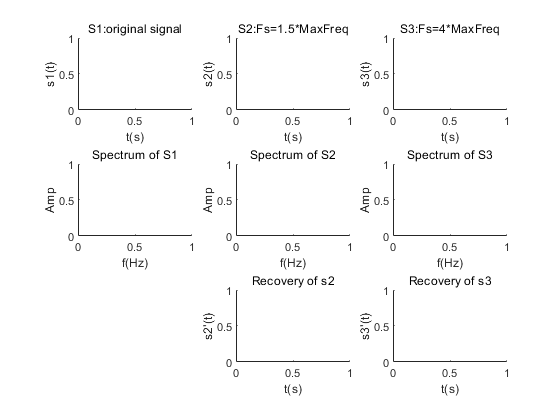

clf; clear;

load("Lab5_signal2.mat");
ft=sig;
N = length(sig);
Fs = N*0.02;
df = Fs/N;
dt = 1/Fs;
T = 5;

subplot(3,3,1);
plot(t,ft);
xlim([0,10]);
ylim([-1.5,1.5]);
title("S1:original signal");
xlabel("t(s)");
ylabel("s1(t)");

y_amp = abs(fftshift(fft(ft))) / N;
f = ((-N/2):(N/2-1)) * df;
subplot(3,3,4);
plot(f,y_amp);
xlim([-2.5,2.5]);
ylim([0,0.35]);
title("Spectrum of S1");
xlabel("f(Hz)");
ylabel("Amp");

fb = 0.39;
disp(fb);

    0.3900



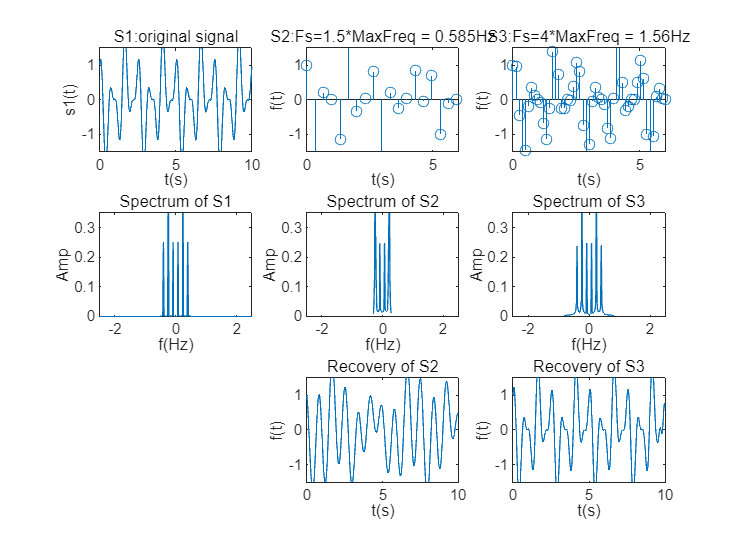


Fs2 = [1.5*fb,4*fb];
ds = 1./Fs2;
sample_interval = floor(ds/dt);
for i = 1:length(sample_interval)
    f_sample = ft(1:sample_interval(i):end);
    t_sample = t(1:sample_interval(i):end);
    Ts = sample_interval(i)*dt;
    sigLen = length(f_sample);
    
    N = sigLen;
    fs = 1/Ts;
    df = fs/N;
    F = fftshift(abs(fft(f_sample)))/sigLen;
    f = (-N/2:N/2-1)*df;

    subplot(3,3,i+1);
    stem(t_sample,f_sample);
    xlim([0,6]);
    ylim([-1.5,1.5]);
    title("S" + num2str(i+1) + ":Fs=" + num2str(Fs2(i) / fb) + "*MaxFreq = " + num2str(Fs2(i)) + 'Hz');
    xlabel('t(s)');
    ylabel('f(t)');
    
    subplot(3,3,i+4);
    plot(f,F);
    xlim([-2.5,2.5]);
    ylim([0,0.35]);
    title("Spectrum of S" + num2str(i+1));
    xlabel('f(Hz)');
    ylabel('Amp'); 
    
    subplot(3,3,i+7);
    sig_recon=zeros(length(t),1);
    for k=1:length(t)
        for n=1:length(f_sample)
            sig_recon(k)=sig_recon(k)+f_sample(n)*sinc(((k-1)*dt-(n-1)*Ts)/Ts);
        end
    end
    plot(t,sig_recon);
    xlim([0,10]);
    ylim([-1.5,1.5]);
    title("Recovery of S" + num2str(i+1));
    xlabel("t(s)");
    ylabel("f(t)");
end

2. Load ***Lab5_music.mat***. It's a piece of music downed in noise. 

2.1 Listen to the original signal and plot the original signal in both time domain and frequency (amplitude-frequency only) domain in a 1*2 subplot. 

2.2 Try to reduce the data amount of the music signal to 5% of the original  signal by sampling. Do the necessary preparations before sampling. 

2.3 Plot the sampled signal in both time domain and frequency (amplitude-frequency only) domain in a 1*2 subplot. (Build-in functions such as downsample/resample is not allowed). Play and listen to it. 

Tips:

Load ***Lab5_music.mat*** with function **load("Lab5_music.mat"** **) **to get the original signal. 

Use** figure** to create a new canva.

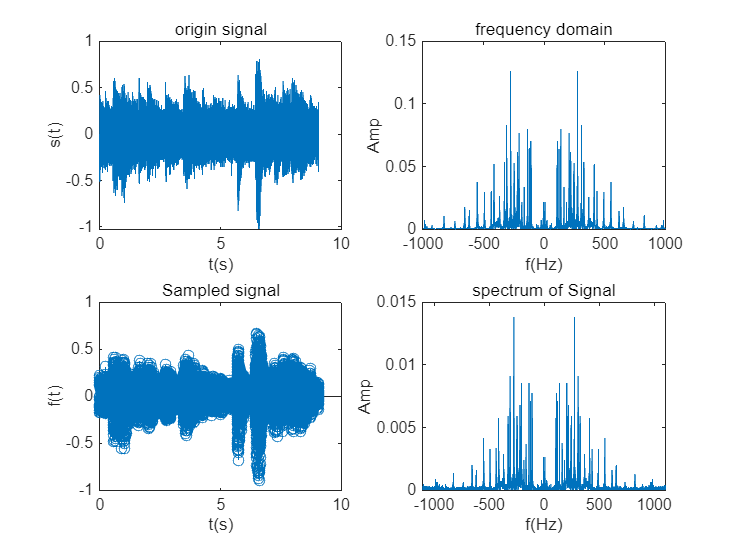

clear;clf;
load("Lab5_music.mat");
sound(signal,Fs);
dt=1/Fs;
N=length(signal);
df=Fs/N;
t=(0:N-1)*dt;
f=(-N/2:N/2-1)*df;
subplot(2,2,1);
plot(t,signal); xlabel('t(s)'); ylabel('s(t)'); title('origin signal');
X=fft(signal);
Y=abs(X)*dt;
Yshift=fftshift(Y);
subplot(2,2,2);
plot(f,Yshift); xlabel('f(Hz)'); ylabel('Amp');xlim([-1000,1000]);
title('frequency domain');
fc=3300;
[b,a]=butter(5,fc/(Fs/2));
signal1 =filter(b,a,signal);
newFs = Fs * 0.05; 
ds=1/newFs;
sample_interval = floor(ds/dt);
f_sample = signal1(1:sample_interval:end);
    t_sample = t(1:sample_interval:end);
    Ts = sample_interval*dt;
    sigLen = length(f_sample);
    
    N = sigLen;
    fs = 1/Ts;
    df = fs/N;
    F = fftshift(abs(fft(f_sample)))/sigLen;
    f = (-N/2:N/2-1)*df;
    subplot(2,2,3);
    stem(t_sample,f_sample); xlabel('t(s)'); ylabel('f(t)');
    title("Sampled signal");

    subplot(2,2,4);
    plot(f,F); xlabel('f(Hz)'); ylabel('Amp');
    title("spectrum of Signal" )

sound(f_sample, newFs);
